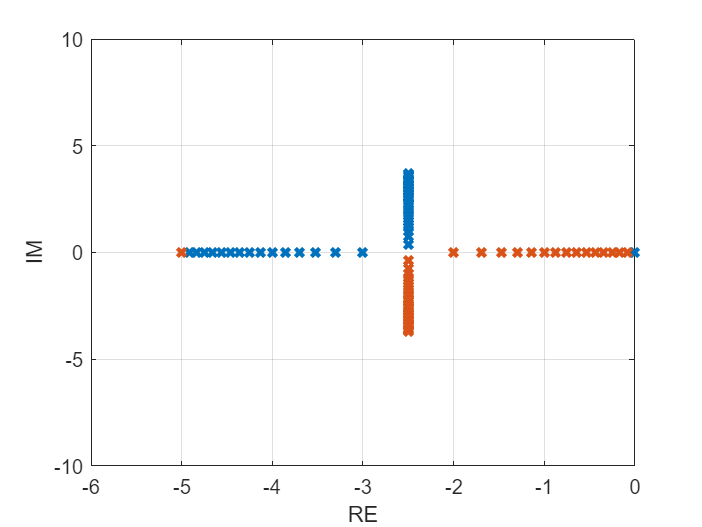

% Root Locus Plot
clear all
K = 0:0.02:1; % range the proportional gain
itot = length(K);
for i = 1:itot % compute CL poles for each gain value
    charpoly = [1 5 20*K(i)]; % characteristic polynomial
    p = roots(charpoly); % compute CL poles
    pcomplex(i,:) = p; % store CL poles
end

plot(pcomplex,'x','LineWidth',2); 
grid;
axis([-6 0 -10 10]) % range of RE and IM axes
xlabel('RE')
ylabel('IM')